在一项热痛实验里，某被试需要在10个试次（trial）中，分别对热量引起的疼痛程度在0到10之间进行评分。编写计算该被试疼痛评分的平均值和标准差的脚本文件stat1.m。

% 随机在0~10之间生成该被试对疼痛的评分
rand('seed',666);
pr = round(rand(1,10)*10)

pr =      6     7     4     3     8     4     2     0     9     4


% 求向量的长度，即trial的数量
len = length(pr);
%求取变量中所有元素的和
s1 = sum(pr);
% 求该被试疼痛评分的平均值
pr_mean = s1/len

pr_mean = 4.7000

% 求该被试疼痛评分的平方和
pr_ss = sum(pr.^2);
% 求该被试疼痛评分的标准差
pr_std = sqrt(pr_ss/len - pr_mean.^2)

pr_std = 2.6476

编写函数文件stat.m求热痛评分的平均值和标准差。

% 随机在0~10之间生成该被试对疼痛的评分
rand('seed',666);
pr1 = round(rand(1,10)*10)

pr1 =      6     7     4     3     8     4     2     0     9     4


[pr_mean pr_std] = stat(pr1)

pr_mean = 4.7000

pr_std = 2.6476

ans = 2.7909

`例 下列语句计算复数`**x**`的值，分别用 `**fprintf**`和`**disp**`显示。` 

%复数
x=2*(1-2*i)^3;
%连接成字符串
str=['disp: x = ' num2str(x)];
%显示字符串
disp(str);

disp: x = -22+4i


fprintf('fprintf: x = %8.4f\n',x);

fprintf: x = -22.0000


利用if语句计算热痛评分的均值。要求：①如果均值大于4分，报告均值；②如果均值小于4分，报告均值和4的差值。

rand('seed',1);
pr = round(rand(1,10)*10)

pr =      5     5     4     1     4     7     1     1     4     0


if mean(pr)>=4
    disp('被试对疼痛的平均评分大于等于疼痛阈限');
    fprintf('疼痛评分的平均值为：%g',vpa(mean(pr)));
else
    disp('被试对疼痛的平均评分小于疼痛阈限'); 
    fprintf('疼痛评分的平均值到4分的差值为：%g',vpa(4-mean(pr)));
end

被试对疼痛的平均评分小于疼痛阈限


疼痛评分的平均值到4分的差值为：0.8

在热痛实验中，被试需要在0~10之间对感受到的热量进行评分。评分标准为：0分是没有感到任何感觉；1~3分是发烫的感觉；4分是刚刚感觉到疼痛，即疼痛阈限；5~10分是疼痛依次递增直到无法忍受。根据疼痛评分，分别执行相应语句。

% 输入热痛评分
score = input('请输入疼痛评分：');
% 情况切换语句
switch score
    case num2cell(8:10);
        disp('高痛！')
    case num2cell(5:7);
        disp('低痛。')
    case num2cell(4);
        disp('疼痛阈限。')
    case num2cell(1:3);
        disp('发烫的感觉。')
    case num2cell(0);
        disp('没有任何感觉。')
    otherwise
        disp('请在0~10之间输入疼痛评分！')
end

低痛。


在处理心理学数据时，经常会遇见二分类问题，例如给定某些值（身高、体重）的数据，去判断性别是男是女。我们无法直接对向量进行判断分类结果，为此我们引入了logistics函数来判断样本归属于每个类别的概率，函数表达式为log(x) = 1/ (1+ exp(-k*x))。其中k为常数，我们来看看不同的k值是如何影响logistics函数的。

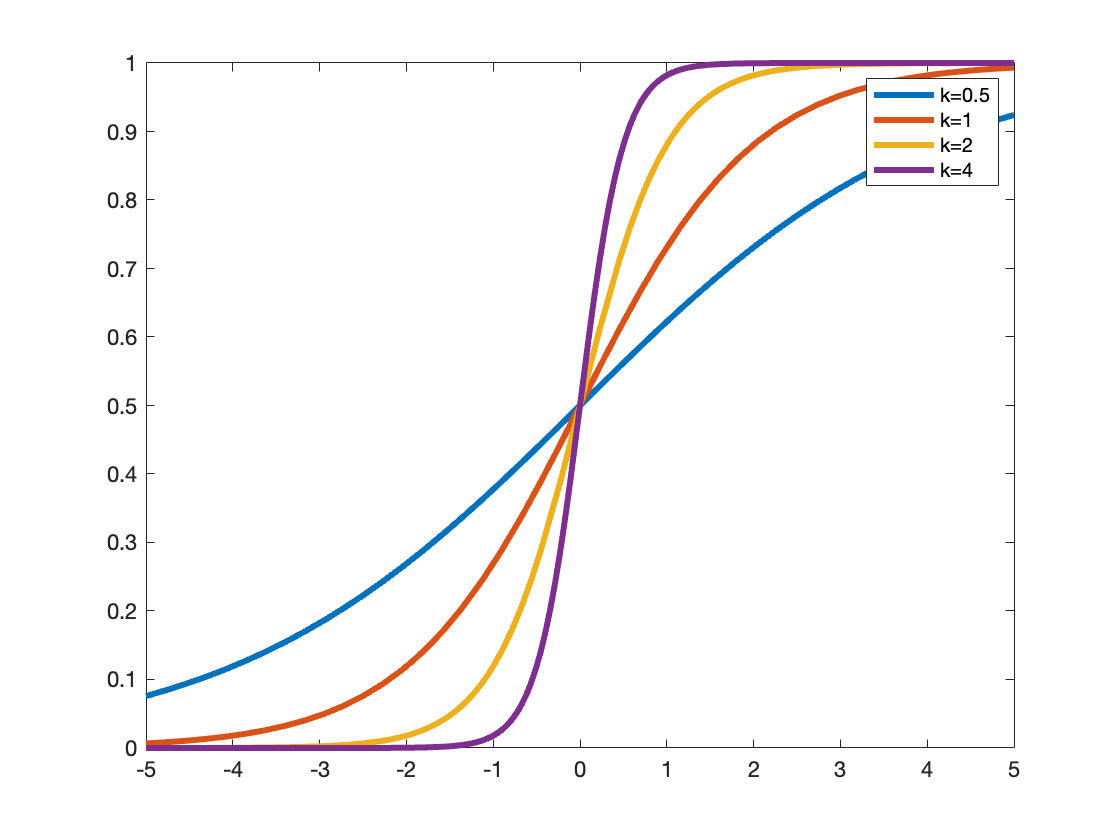

% 设4种k值
k = [0.5 1 2 4];
% 设置循环
for i=1:length(k)
    fplot(@(x) 1./(1+exp(-k(i)*x)),[-5,5],'LineWidth',3)
    leg_str{i}=['k=',num2str(k(i))];
    hold on
end
legend(leg_str)

`例 利用`**rand**`函数产生`**10**`个随机数，然后利用嵌套`**for**`循环进行从小到大排序。`  

a=rand(10,1);
for i=1:length(a)
   for j=1:length(a)-1
       if a(j)<a(j+1)
          t=a(j);
          a(j)=a(j+1);
          a(j+1)=t;
       end
   end
end
a

a =     0.7178
    0.6617
    0.5729
    0.5281
    0.5083
    0.4714
    0.4460
    0.4319
    0.1922
    0.1449


分步演示：

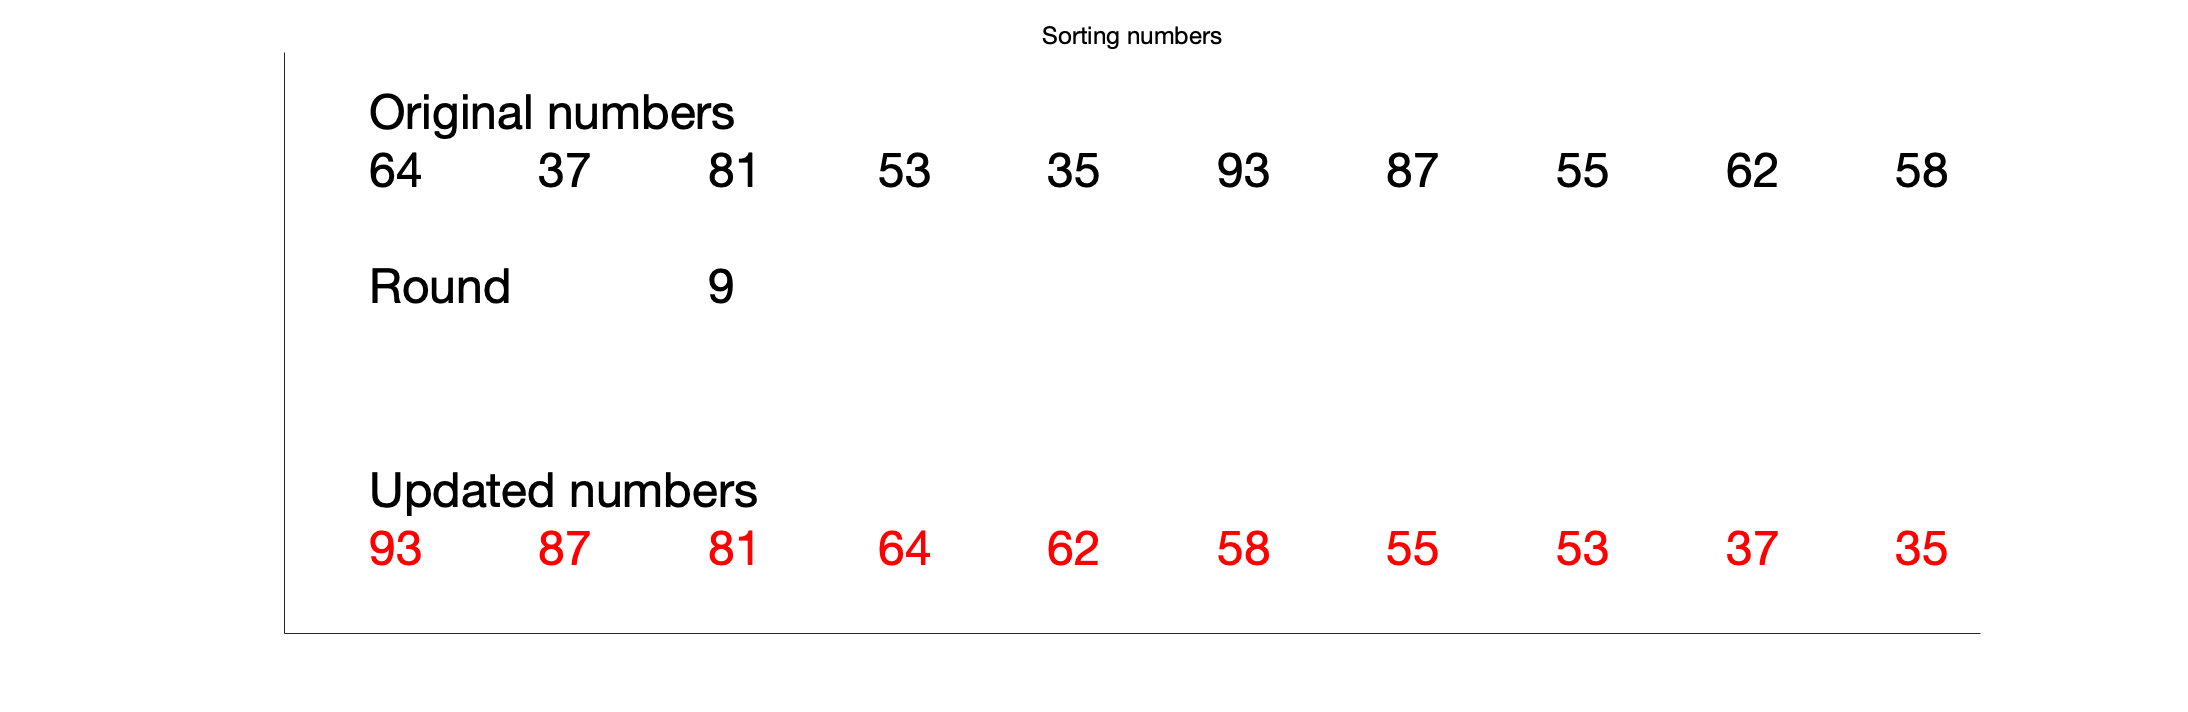

clear;
x=[64 37 81 53 35 93 87 55 62 58];
% 计算随机数的长度 
n=length(x);

figure,title('Sorting numbers');
set(gcf,'unit','normalized','position',[0.2,0.2,0.64,0.32]);
set(gca,'XTick',[], 'YTick', []);
text(0.05,0.9,'Original numbers','FontSize',24);
text(0.05,0.25,'Updated numbers','FontSize',24);
for m=1:10
    text(0.1*m-0.05,0.8,num2str(x(m)),'FontSize',24);
end
pause(1);

% 进行排序
r1=text(0.05,0.6,'Round','FontSize',24);
r2=text(0.15,0.6,'1','FontSize',24);
for i=1:n-1
    delete(r2);
    r2=text(0.25,0.6,num2str(i),'FontSize',24);
    for j=n:-1:i+1
        t1=text(0.1*j-0.05,0.4,num2str(x(j)),'FontSize',24);
        t2=text(0.1*(j-1)-0.05,0.4,num2str(x(j-1)),'FontSize',24);
        
        if x(j)>x(j-1)
           y=x(j);
           x(j)=x(j-1);
           x(j-1)=y;
           ss=text(0.9,0.9,'SWAP!!','FontSize',36,'Color','r');pause(0.5);delete(ss);
        end
        
           delete(t1);
           t1=text(0.1*j-0.05,0.4,num2str(x(j)),'FontSize',24);pause(0.5);delete(t1);
           delete(t2);
           t2=text(0.1*(j-1)-0.05,0.4,num2str(x(j-1)),'FontSize',24);pause(0.5);delete(t2);                
    end   
    
    text(0.1*i-0.05,0.15,num2str(x(i)),'FontSize',24,'Color','r');
    pause(1);
    
end

text(0.1*n-0.05,0.15,num2str(x(n)),'FontSize',24,'Color','r');

`对被试10个试次的疼痛评分利用嵌套`**for**`循环进行从小到大排序，并记录下变换后试次的顺序。`

% 初始化疼痛评分和序列
rand('seed',666);
pr = round(rand(1,10)*10)

pr =      6     7     4     3     8     4     2     0     9     4


seq =[1:length(pr)];
n = length(pr);
% 两两比较
for i=[1:n]
    for j=[i:n]
        if pr(i) > pr(j)
            for names={'pr','seq'}
                eval(['smaller_' char(names) '=' char(names) '(j);'])
                eval([char(names) '(j)=' char(names) '(i);'])
                eval([char(names) '(i)=' 'smaller_' char(names) ';'])
            end
        end
    end
end
pr_sorted = pr

pr_sorted =      0     2     3     4     4     4     6     7     8     9


seq_sorted = seq

seq_sorted =      8     7     4     3     6    10     1     2     5     9


rand('seed', 36);
pr = round(rand(1, 10) * 10)

pr =      5     6     6     4     6     5     2     8     3     2


sort(pr)

ans =      2     2     3     4     5     5     6     6     6     8


在一项恐惧学习实验中，研究人员使用**同一温度**的热痛来条件化被试的恐惧反应。如果被试对热痛的评分在连续3个试次中都小于4分，我们武断地定义在此之后的所有试次都无效。求有效试次n的值。

% 初始化
rand('seed',6); pr = round(rand(1,30)*10)

pr =      1     8     1     6     6     3     7     5     2     2     2     8     9     3    10     6     7     0     2     4     2     0     0     5     4     8     1     4     6     4


n=2;
% 设置循环
while all(pr(n-1:n+1)<4)==0
    n = n+1;
end
fprintf('有效试次共%d个！',n+1)

有效试次共11个！

`例 求一个值`**n**`，使`**n**`！最大但小于`**10^50**`。`  

%初始化
r=1;k=1;
%做循环
while r<1e50
r=r*k;
k=k+1;
end
k=k-1;r=r/k;k=k-1;
% 输出结果
disp(['The',num2str(k),'!is',num2str(r)])

The41!is3.34525266131638e+49


**例****2**** 在一****项自适应学习****实验中，研究人员使用****不同温度****的热痛来条件化被****试反应****。热刺激的初始温度为****42****度，如果被试连续****3****次对该热刺激的评分小于****4****时，热刺激需提高****1****度（当调整到新温度后重置，即仍需****3****次评分小于****4****才会进行调整）；如果被试连续****3****次评分等于****10****时，热刺激需要减小****1****度以避免伤害到被试****。试编写脚本从****被试的评分****中实时调整热****痛刺激的****温度。**

clc;clear
% 给定该被试在整个实验中的热痛评分
pr = [10,4,1,3,4,6,3,6,7,2,1,1,1,1,1,1,10,10,10,10,1,3,3,4,5,10,10,10,8,10]

pr =     10     4     1     3     4     6     3     6     7     2     1     1     1     1     1     1    10    10    10    10     1     3     3     4     5    10    10    10     8    10


len = length(pr);
% 给定初试温度
x =42;
% 初始化
i = 3;
temp = [42 42 42];
% 开始循环
while i <= length(pr)
    a=pr(i-2:i);
    if all(a(:)<4)
         x=x+1;
         temp=[temp,repelem(x,3)];
         i = i+3;
    elseif all(a(:)==10)
         x=x-1;
         temp=[temp, repelem(x,3)];
         i = i+3;
    else
        temp=[temp,x];
        i = i+1;
    end
end
% 热刺激温度
temp = temp(1:len)

temp =     42    42    42    42    42    42    42    42    42    42    42    42    43    43    43    44    44    44    44    43    43    43    43    44    44    44    44    44    43    43


`分析行为数据（如热痛评分、分类选择）时，我们常常会用到模拟数据。利用`**menu**`函数输入选择参数`**ch**`。当`**ch=pr**`时，产生10个单被试在`**[0,10]**`之间均匀分布的热痛评分；当`**ch=prs**`时，产生10个双被试在`**[0,10]**`之间均匀分布的热痛评分；当`**ch=binary**`时，产生0/1中均匀分布的随机数；当`**ch=noise**`时，产生均值为1，方差为2的正态分布随机数。（要求使用`**switch**`函数）`  

% 初始化
clear all
clc
% 建立一个菜单
unit = menu('ch','pr','prs','binary','noise');
switch unit
    case 1
        pr = round(rand(1,10)*10)
    case 2
        prs = round(rand(2,10)*10)
    case 3
        binary = randi([0,1], [1,10])
    case 4
        noise = 1 + sqrt(2)*randn(1,10)
    otherwise
        disp('输入错误！')
end

输入错误！


clear all
clc

unit = menu('choose a letter', 'a', 'b', 'c', 'd');
switch unit
    case 1
        pr = round(rand(1, 10) * 10)
    case 2
        prs = round(rand(2,10)*10)
    case 3
        binary = randi([0,1], [1,10])
    case 4
        noise = 1 + sqrt(2)*randn(1,10)
    otherwise
        disp('输入错误！')
end

pr =      0     8    10     6     2     5     4     8     6     8
